clear; clf; close all;

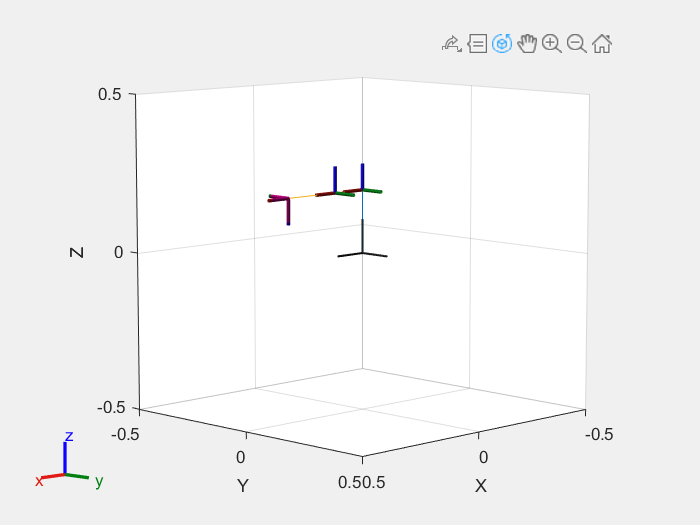

robot = RA_CreateRobot;
show(robot);

des_pos = [-0.15, 0.15, 0.1];
init_guess = [0 0];
[sola, stts] = RA_InverseKinematics(robot, des_pos, init_guess);

actual_pos = RA_ForwardKinematics(robot, sola)

actual_pos =    -0.9806    0.1961    0.0000   -0.1500
    0.1961    0.9806    0.0000    0.1500
         0    0.0000   -1.0000    0.2000
         0         0         0    1.0000


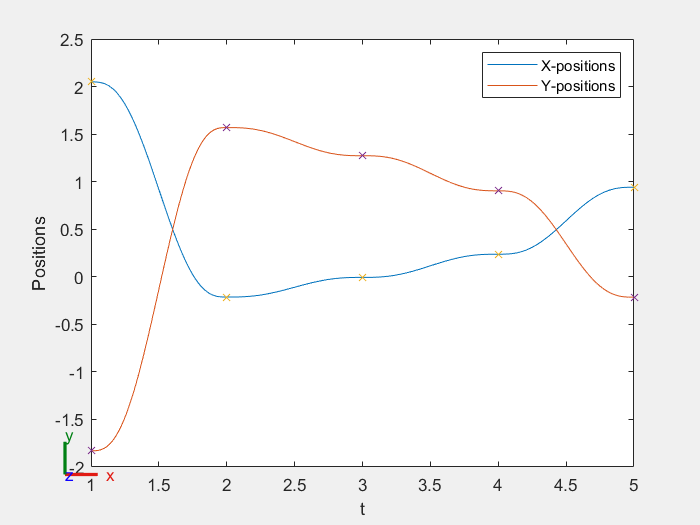

wpts = [
        0.14 0.16 0.18 0.20 0.22;
        0.15 0.17 0.19 0.21 0.23;
        0.2 0.2 0.2 0.2 0.2
        ];
tpts = 1:5; tvec = 1:0.01:5;
[q, qd, qdd, pp] = RA_GenerateJointTrajectory(robot, wpts, tpts, tvec, [0, 0]);

nSamples = length(q);
x = zeros(size(wpts,1), nSamples);
solTransform = eye(4);
for i=1:nSamples
    solTransform = RA_ForwardKinematics(robot, q(:,i)');
    x(:, i) = solTransform(1:3, 4);
end
% x=x';

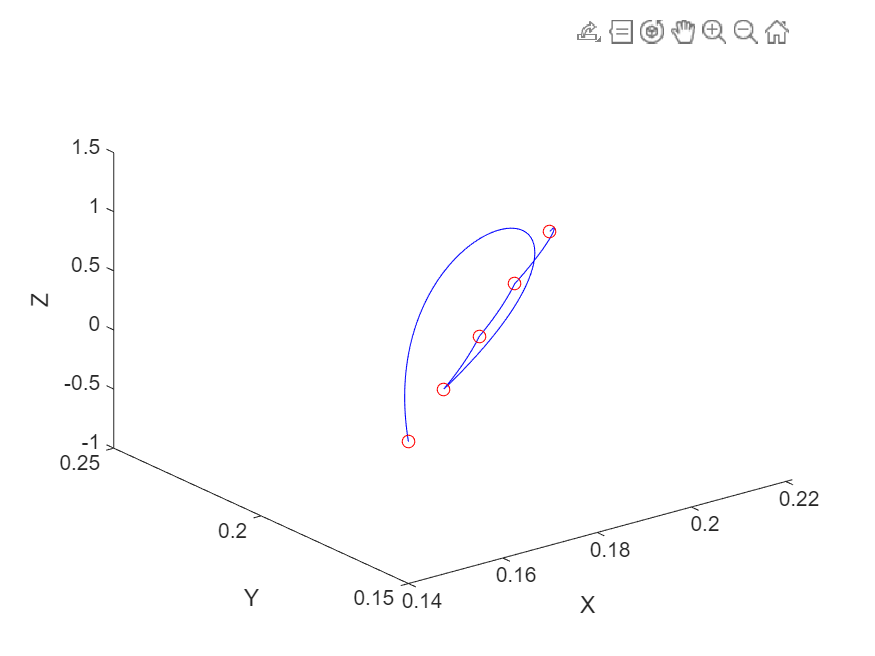

figure
plot3(x(1,:),x(2,:),x(3,:),'-b', wpts(1,:),wpts(2,:),wpts(3,:),'or')
xlabel('X'); ylabel('Y'); zlabel('Z');